# 7. Computer Vision Application - Object Detection(2/2)

load('petGT.mat')

## Train a R-CNN (Regions with Convolutional Neural Networks)

You can train three different types of R-CNNs : R-CNN, Fast R-CNN, and Faster R-CNN. The corresponding functions are 

- `trainRCNNObjectDetector`

- `trainFastRCNNObjectDetector -> miniBatchSize 1이어야함`

- `trainFasterRCNNObjectDectector -> miniBatchSize 1이어야함`

These networks differ between training time and dectection time. For example, a R-CNN can be trained quickly, but the time to detect a new image is slower than a Faster R-CNN network.

Choice of which network to use depends on your application. The Fast and Faster R-CNNs are designed to improve detection performance with a large number of regions at the cost of training time.

이러한 네트워크는 훈련 시간과 탐지 시간이 다릅니다. 예를 들어, R-CNN은 빠르게 훈련될 수 있지만 새 이미지를 감지하는 시간은 Faster R-CNN 네트워크보다 느립니다.

사용할 네트워크 선택은 애플리케이션에 따라 다릅니다. Fast and Faster R-CNN은 훈련 시간을 희생하면서 많은 수의 영역에 대한 탐지 성능을 향상시키도록 설계되었습니다.

#### NOTE: When you train R-CNNs, the Mini Batch Size should be 1.

opts = trainingOptions("sgdm","InitialLearnRate",0.0001,...
    "MaxEpochs",5,"MiniBatchSize",1)

opts =   TrainingOptionsSGDM - 속성 있음:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 5
                   MiniBatchSize: 1
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
                 

detector = trainFasterRCNNObjectDetector(petGT,"alexnet",opts)

*************************************************************************
다음 객체 클래스에 대해 Faster R-CNN 객체 검출기 훈련:

* Ginny
* Lucy
* Madeline
* Kima
* Susan



%이미지의 바운드 박스 크기가 다 다르기 때문에, 대부분 이미지 resizing을 다 가지고 있다. 36번을 보면, 바운드 박스가
%처리가 안되어있다.

It take long to train a Faster R-CNN using a CPU. Use a trained detector instead.

load detector.mat

## Use an Object Detector

###     Detect Obejcts

This code uses `detector` to detect pet faces in `dogim`.

`    [bboxes,scores,labels] = detect(detector,dogim)`

dogim = imread("testImages/Ginny.jpg")

dogim = 308×410×3 uint8 배열
dogim(:,:,1) =

   100   145   105   119   111   146   129   137   131   159   124   104    89    99   134    88    88    82   136   138   140   141   152   134   141   132   134   138   137   139   134   118   116   107    92    87    98   120   136   140   161   161   168   158   186   190   224   241   229   187   173   137   144   139   143   150   128   121   121   127   142   135   121   146   146   125   141   142   140   131   110   127   127   123   134   141   131   144   122   134   129   144   135   129   154   194   129    95   105    91    82   118   140   114   104   105   112   112   117   109   122   124   144   121   124   128   148   138   127   135   124   115   114   113   122   113   125   121   137   140   124   133   114   122   124    97    90    75    76    75    80   101    99   132   119   113    84    38    70    60    58    72    80    59    84    81    92    56    89    92    63    75    98    74    61   107   114    65    81   

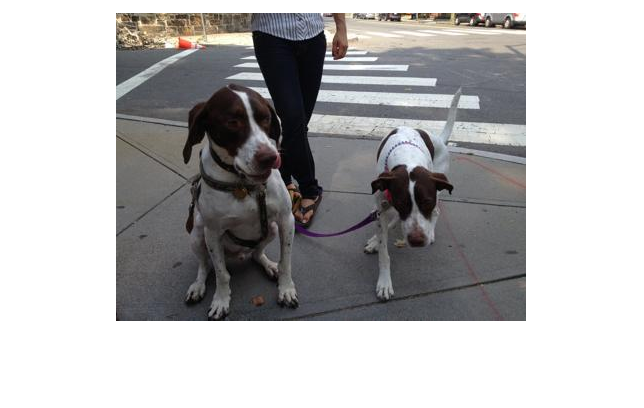

imshow(dogim)

% Detect Ginny in a test image.
[bboxes,scores,labels] = detect(detector,dogim)

bboxes =     74    65   105   109
   251   143   108    99


scores = 2×1 single 열 벡터
    0.9276
    0.6699


labels = 2×1 categorical 배열
     Ginny 
     Ginny 


% 바운드 박스(x,y,width,height)

###     Insert bounding boxes and labels

The output label from detect is a categorical array. To use this label with `insertObjectAnnotation`, you need to convert it to text. You can use the `cellstr` function to do this. 

detectedDogs = insertObjectAnnotation(dogim,"rectangle",bboxes,labels)

detectedDogs = 308×410×3 uint8 배열
detectedDogs(:,:,1) =

   100   145   105   119   111   146   129   137   131   159   124   104    89    99   134    88    88    82   136   138   140   141   152   134   141   132   134   138   137   139   134   118   116   107    92    87    98   120   136   140   161   161   168   158   186   190   224   241   229   187   173   137   144   139   143   150   128   121   121   127   142   135   121   146   146   125   141   142   140   131   110   127   127   123   134   141   131   144   122   134   129   144   135   129   154   194   129    95   105    91    82   118   140   114   104   105   112   112   117   109   122   124   144   121   124   128   148   138   127   135   124   115   114   113   122   113   125   121   137   140   124   133   114   122   124    97    90    75    76    75    80   101    99   132   119   113    84    38    70    60    58    72    80    59    84    81    92    56    89    92    63    75    98    74    61   107   114 

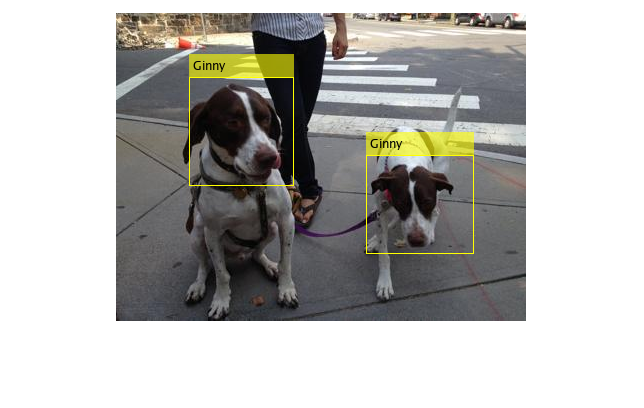

imshow(detectedDogs)

###     Insert bounding boxes, labels and scores

You can see the bounding boxes and the labels inserted in the image but sometimes, you need to insert the scores in the image as well.

% labelScores = "Ginny0.9276" %수기로 쓴 다음, insertObjectAnnotation에다 넣음. 
% 1.
% detectedDogs = insertObjectAnnotation(dogim,"rectangle",bboxes,labelScores)
% imshow(detectedDogs)
% 2.
% labelScores = cell([2,1]) % cell(size(labels)), score = Float, labels = categorical -> cell 사용하면 됨. 숫자->문자(=num2str)
% labelScores = num2str(scores(1)) %char(labels(1)), cellstr(labels(1))
% detectedDogs = insertObjectAnnotation(dogim,"rectangle",bboxes,labelScores)
% imshow(detectedDogs)

%     labelScores{k} = [char(labels(k)), num2str(scores(k))]
labelScores = cell(size(labels))

labelScores = 2×1 cell 배열
    {0×0 double}
    {0×0 double}



for i = 1:length(labels)
    labelScores{i} = [char(labels(i)), ' : ', num2str(scores(i))]
    %labelScores{i} = [char(labels(i)), ' ', num2str(scores(i))] 중간에 빈 문자를
    %넣을 수도 있음
end

labelScores = 2×1 cell 배열
    {'Ginny : 0.92762'}
    {0×0 double       }


labelScores = 2×1 cell 배열
    {'Ginny : 0.92762'}
    {'Ginny : 0.66992'}



detectedDogs = insertObjectAnnotation(dogim,"rectangle",bboxes,labelScores)

detectedDogs = 308×410×3 uint8 배열
detectedDogs(:,:,1) =

   100   145   105   119   111   146   129   137   131   159   124   104    89    99   134    88    88    82   136   138   140   141   152   134   141   132   134   138   137   139   134   118   116   107    92    87    98   120   136   140   161   161   168   158   186   190   224   241   229   187   173   137   144   139   143   150   128   121   121   127   142   135   121   146   146   125   141   142   140   131   110   127   127   123   134   141   131   144   122   134   129   144   135   129   154   194   129    95   105    91    82   118   140   114   104   105   112   112   117   109   122   124   144   121   124   128   148   138   127   135   124   115   114   113   122   113   125   121   137   140   124   133   114   122   124    97    90    75    76    75    80   101    99   132   119   113    84    38    70    60    58    72    80    59    84    81    92    56    89    92    63    75    98    74    61   107   114 

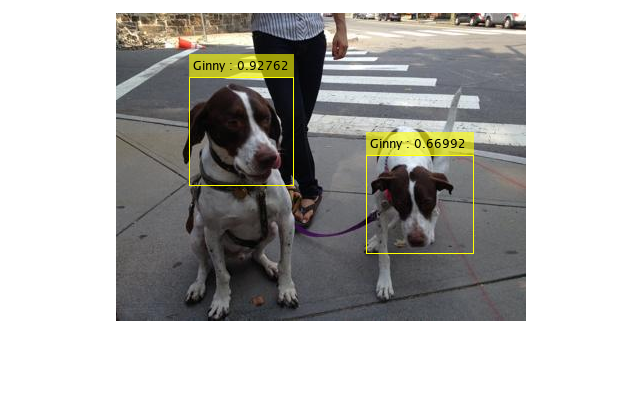

imshow(detectedDogs)

## Threshold Detections

You may want to apply a threshold the results to only include confident predictions. Extract detections above 90% confidence.

%90퍼센트 이상만 표시
idx = (scores > 0.9)

idx = 2×1 logical 배열
   1
   0


bbox = bboxes(idx,:)

bbox =     74    65   105   109


labelScore = labelScores(idx, :)

labelScore = 1×1 cell 배열
    {'Ginny : 0.92762'}


detectedDogs = insertObjectAnnotation(dogim,"rectangle",bbox,labelScore)

detectedDogs = 308×410×3 uint8 배열
detectedDogs(:,:,1) =

   100   145   105   119   111   146   129   137   131   159   124   104    89    99   134    88    88    82   136   138   140   141   152   134   141   132   134   138   137   139   134   118   116   107    92    87    98   120   136   140   161   161   168   158   186   190   224   241   229   187   173   137   144   139   143   150   128   121   121   127   142   135   121   146   146   125   141   142   140   131   110   127   127   123   134   141   131   144   122   134   129   144   135   129   154   194   129    95   105    91    82   118   140   114   104   105   112   112   117   109   122   124   144   121   124   128   148   138   127   135   124   115   114   113   122   113   125   121   137   140   124   133   114   122   124    97    90    75    76    75    80   101    99   132   119   113    84    38    70    60    58    72    80    59    84    81    92    56    89    92    63    75    98    74    61   107   114 

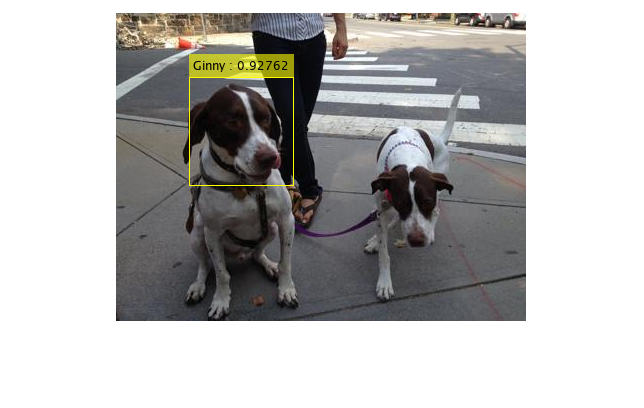

imshow(detectedDogs)